## 3. Análise no domínio da frequência

### 3.2. Critério de estabilidade de Nyquist

#### 3.2.1. O diagrama de Nyquist

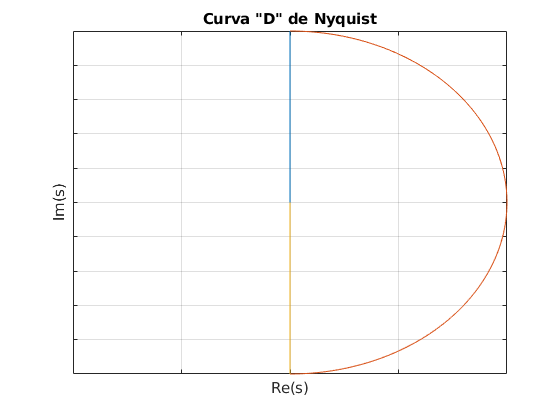

Nmax = 4;
w_vec = logspace(-3,Nmax,100);
R = 10^Nmax;
theta_vec = linspace(pi/2,-pi/2,100);
s1 = 1i*w_vec;
s2 = R*exp(1i*theta_vec);
figure();
plot([s1]); hold all; plot(s2); plot(-s1); axis([-10^Nmax 10^Nmax -10^Nmax 10^Nmax]); 
grid on; title('Curva "D" de Nyquist'); xlabel('Re(s)'); ylabel('Im(s)');
set(gca,'XTickLabel',[], 'YTickLabel', [])


$$G(s) = \frac{1}{s+1}$$


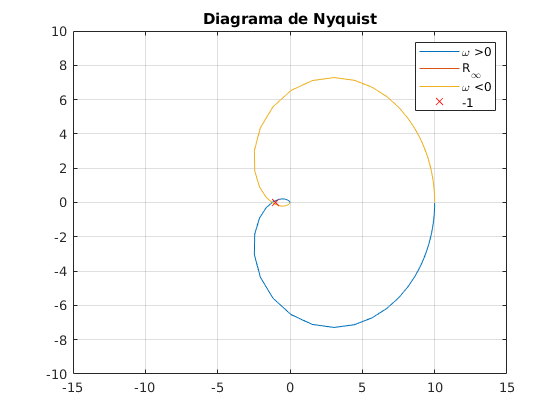

a = 1;
G = @(s) 10./((s+a).^3);
figure();
plot(G([s1])); hold all;title('Diagrama de Nyquist')
plot(G((s2))); plot(G(-flip(s1))); 
plot([-1+0.00000000001i], 'xr'); axis([-1.5 1.5 -1 1]*10)
legend('\omega >0 ', 'R_\infty', '\omega <0', '-1'); grid on;

E se existirem polos no eixo imaginário?

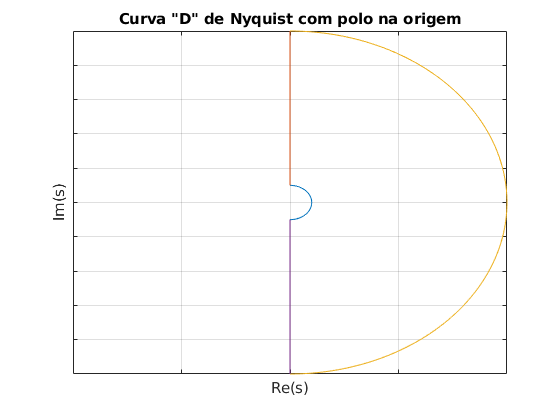

Nmax = 3;
w_vec = logspace(2,Nmax,100);
R = 10^Nmax;
theta_vec = linspace(pi/2,-pi/2,100);
Rpequeno = 100;
s0 = Rpequeno*flip(exp(1i*theta_vec));
s1 = 1i*w_vec;
s2 = R*exp(1i*theta_vec);
figure();
plot(s0);hold all;plot(s1);plot(s2);plot(-s1);
axis([-10^Nmax 10^Nmax -10^Nmax 10^Nmax]); 
grid on; title('Curva "D" de Nyquist com polo na origem'); xlabel('Re(s)'); ylabel('Im(s)');
set(gca,'XTickLabel',[], 'YTickLabel', []);

exemplo

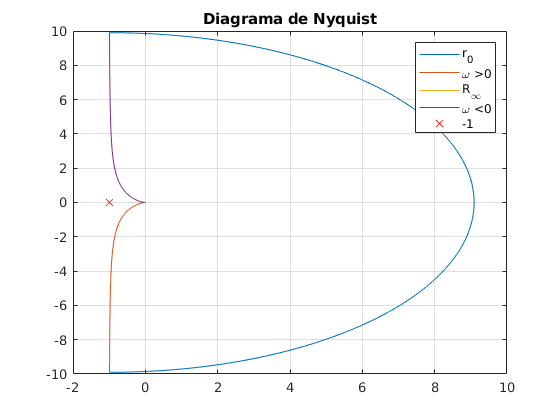

Nmax = 2;
Nmin = -1;
w_vec = logspace(Nmin,Nmax,100);
R = 10^Nmax;
theta_vec = linspace(pi/2,-pi/2,100);
Rpequeno = 10^Nmin;
s0 = Rpequeno*flip(exp(1i*theta_vec));
s1 = 1i*w_vec;
s2 = R*exp(1i*theta_vec);
G = @(s) 1./s./(s+1);
figure();

plot(G([s0]));hold all;plot(G([s1])); title('Diagrama de Nyquist')
plot(G(s2)); plot(G(-flip(s1))); 
plot([-1+0.00000000001i], 'xr'); %axis([-1.5 1.5 -1 1])
legend('r_0', '\omega >0', 'R_\infty', '\omega <0', '-1'); grid on;

Obtenção do diagrama de Nyquist utilizando a função "nyquist" do Matlab:

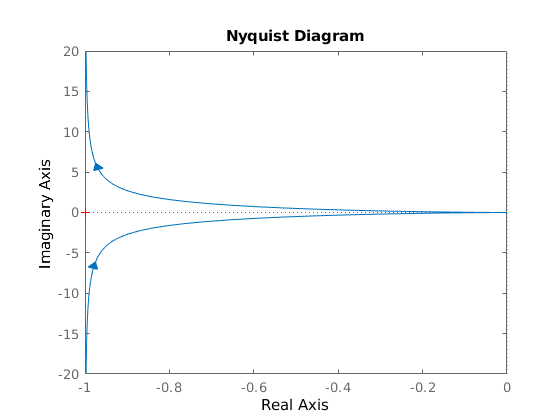

L = 1*tf([1], [1 0])*tf([1],[1 1]);
figure;nyquist(L)

#### 3.2.2. Critério de estabilidade de Nyquist simplificado

Seja L(s) a função de transferência de malha aberta de um sistema realimentado negativamente e assumindo que L não tem polos no semi-plano direito ($\text{Re}(s)\geq 0$) exceto por polos simples no eixo imaginário. O sistema de malha fechada será estável se e somente se a curva fechada dada por $\Omega=\left\{L(j\omega): -\infty< \omega<\infty \right\} 
$não circula o ponto crítico $s = -1$.

#### 3.2.3. Estabilidade condicional

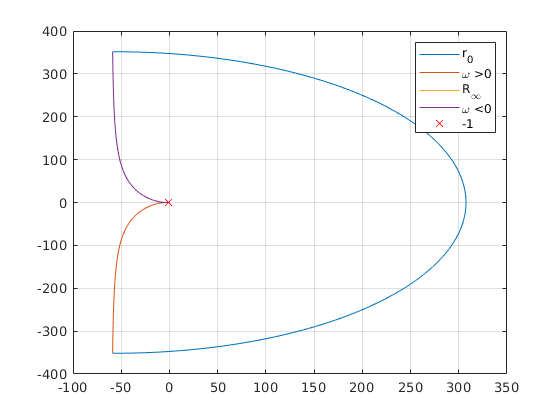

Nmax = 2;
Nmin = -1;
w_vec = logspace(Nmin,Nmax,100);
R = 10^Nmax;
theta_vec = linspace(pi/2,-pi/2,100);
Rpequeno = 10^Nmin;
s0 = Rpequeno*flip(exp(1i*theta_vec));
s1 = 1i*w_vec;
s2 = R*exp(1i*theta_vec);
G = @(s) 01*(s+6).^2./(s+1).^2./s;
figure();

plot(G([s0]));hold all;plot(G([s1]));
plot(G(s2)); plot(G(-flip(s1))); 
plot([-1+0.00000000001i], 'xr'); %axis([-1.5 1.5 -1 1])
legend('r_0', '\omega >0', 'R_\infty', '\omega <0', '-1'); grid on;

### 3.3. Critério geral de Nyquist

**Teorema de estabilidade de Nyquist:**

Considere um sistema de malha fechada com função de transferência de malha aberta L(s) que tem "P" polos na região fechada pelo contorno de Nyquist $\Gamma$. Seja "N" o número de circulos horários feitos por L(s) em torno de -1 quando "s" circula o contorno de Nyquist $\Gamma$ em direção horária. A malha fechada do sistema tem Z = N + P polos no semi-plano direito.

Exemplo:  pêndulo invertido:


$$P(s) = \frac{1}{s^2-1}$$


utilizando um controlador "PD":


$$C(s) = k(s+2)$$


Função de transferência de malha aberta: $L(s) = \frac{k(s+2)}{s^2-1}$

L = tf([1 2], [1 0 -1])

L =
 
   s + 2
  -------
  s^2 - 1
 
Continuous-time transfer function.



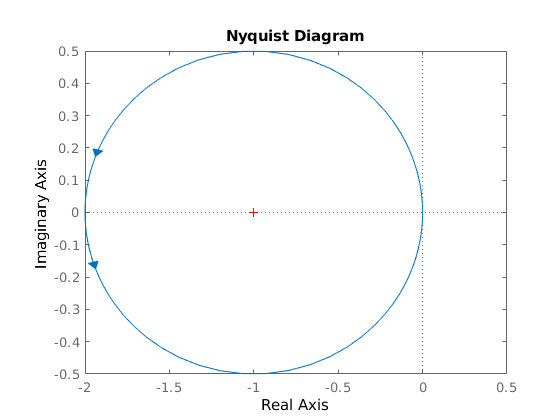

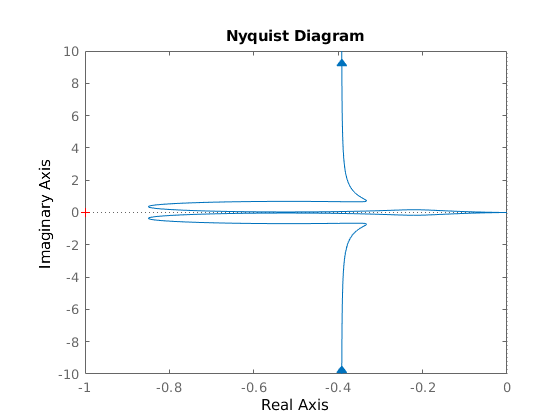

figure();
nyquist(L)

Pode ser calculado verificando a frequência onde a fase de L(s) é -180 graus: ***frequência de cruzamento de fase*** $\omega_{cf}$


$$g_m=\frac{1}{|L(j\omega_{pc})|$$


**Margem de fase **$\phi_m$ é a quantia de atraso de fase necessária para atingir o limite de estabilidade.

Pode ser calculado a partir na menor frequência onde $|L(j\omega)|$ vale 1:** frequência de cruzamento de ganho** $\omega_{cg}$.


$$\phi_m = 180º +\arg L(j \omega_{cg})$$


#### 3.4.2 Margem de estabilidade $s_m$e margem de atraso

**Margem de estabilidade** $s_m$ é a menor distância entre o diagrama de Nyquist e o ponto crítico (-1)

**Margem de atraso **$\tau_a$ é o menor atraso de tempo necessário para fazer um sistema instável.

Ou seja: $e^{-s\tau_a}L(s)$

Alguns critérios usuais considerados razoáveis para as margens de estabilidade:

- Margem de ganho $g_m$: entre 2 e 5

- Margem de fase $\phi_m$: entre 30 e 60 graus

- Margem de estabilidade $s_m$: entre 0.5 e 0.8

#### 3.4.3 Obtenção das margens no Matlab

Ver vídeo. alguns comandos:

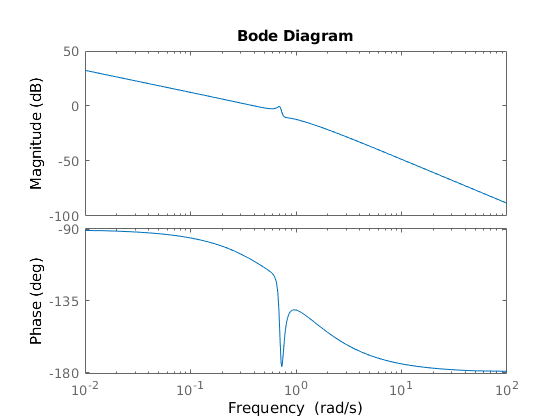

L = 0.38*tf([1 0.1 0.55],[1 0.06 0.5])*tf(1,[1 0])*tf(1,[1 1]);

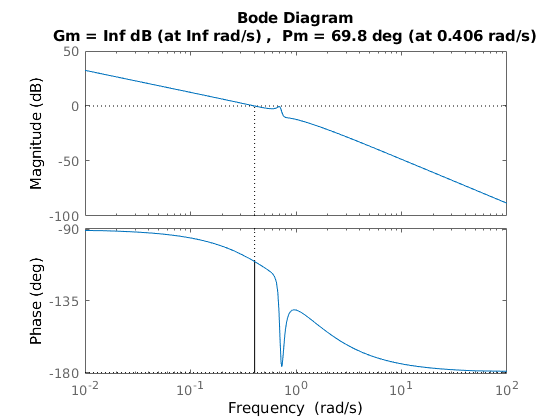

figure(); nyquist(L)

ans = struct with fields:
     GainMargin: Inf
    GMFrequency: Inf
    PhaseMargin: 69.7721
    PMFrequency: 0.4058
    DelayMargin: 3.0010
    DMFrequency: 0.4058
         Stable: 1


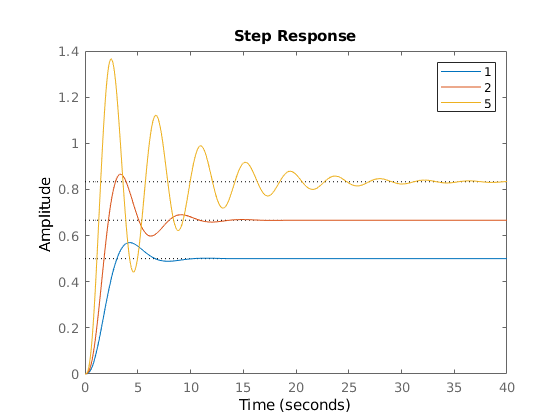

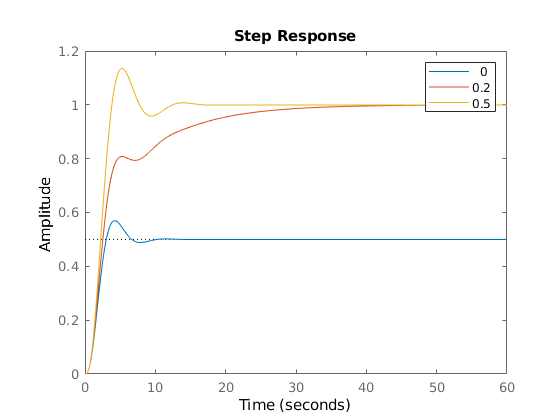

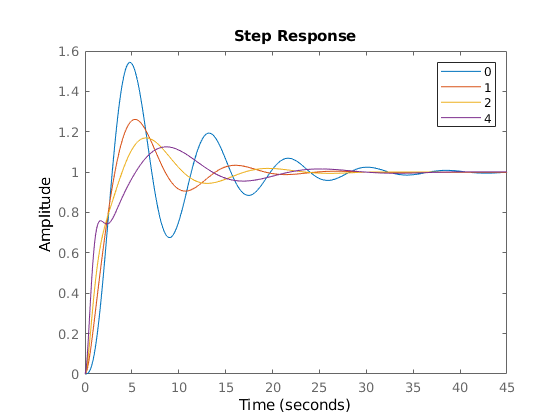

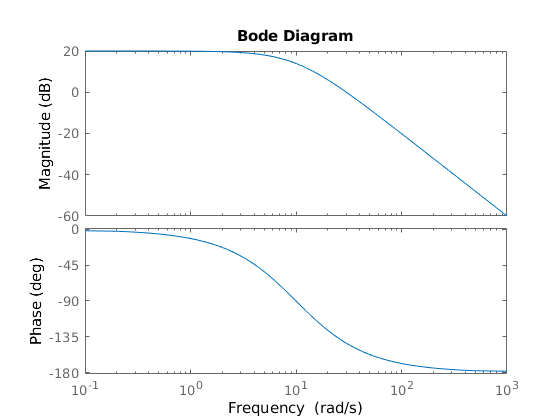

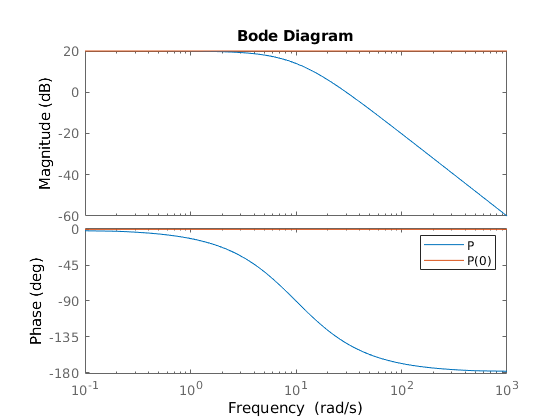

G =
 
              1000 s^3 + 20000 s^2 + 100000 s
  --------------------------------------------------------
  s^6 + 40 s^5 + 600 s^4 + 5000 s^3 + 30000 s^2 + 100000 s
 
Continuous-time transfer function.



Gconst =
 
     10 s
  ----------
  s^2 + 10 s
 
Continuous-time transfer function.



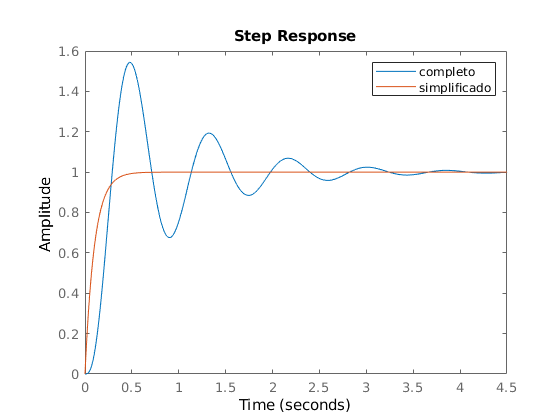

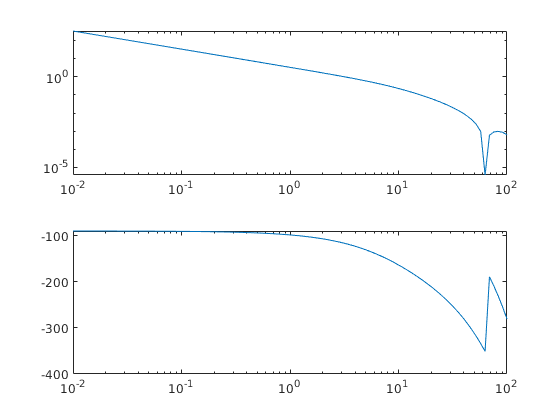

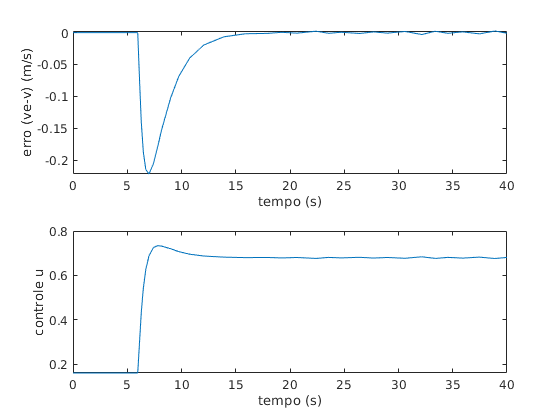

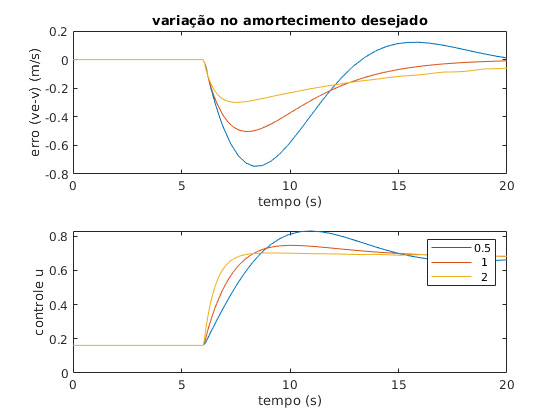

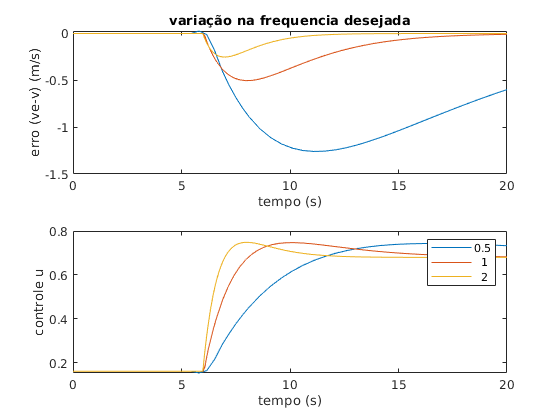

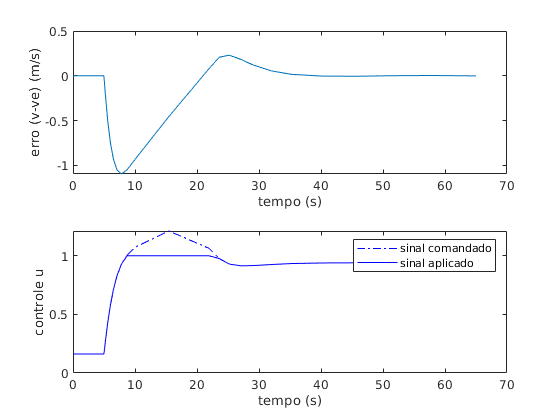

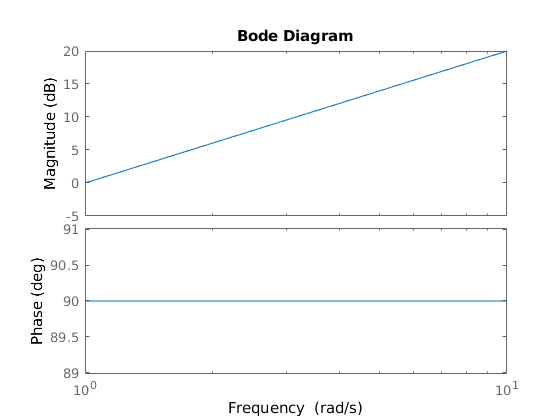

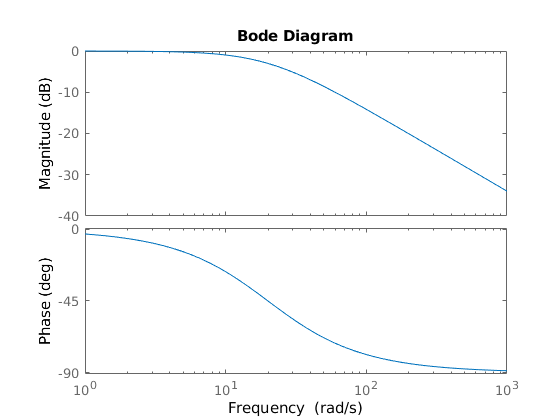

G =
 
    s^3 - 2 s^2 + s
  -------------------
  s^4 - s^3 - s^2 + s
 
Continuous-time transfer function.



                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -1.00e+00     1.00e+00       1.00e+00         1.00e+00    
  1.00e+00    -1.00e+00       1.00e+00        -1.00e+00    
  1.00e+00    -1.00e+00       1.00e+00        -1.00e+00    


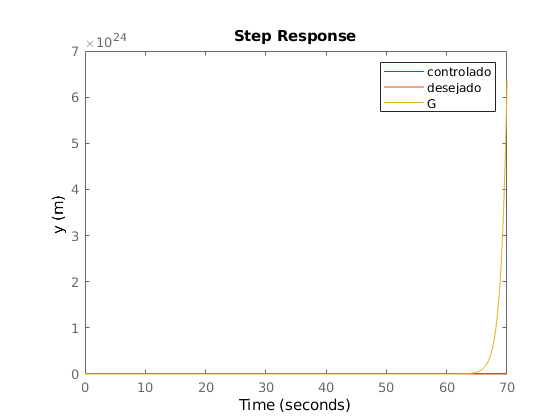

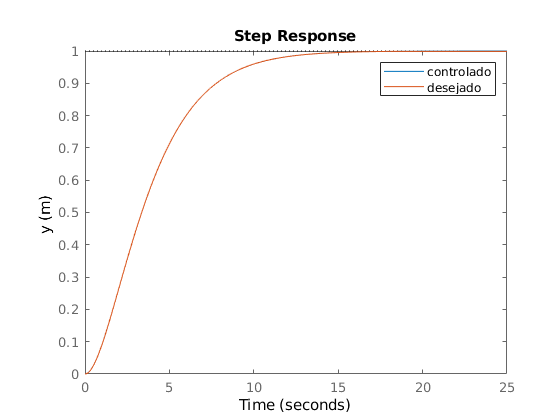

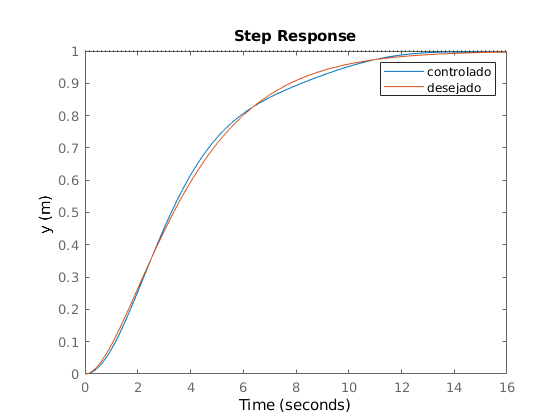

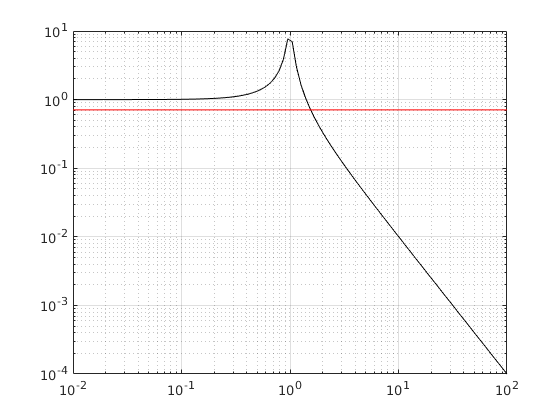

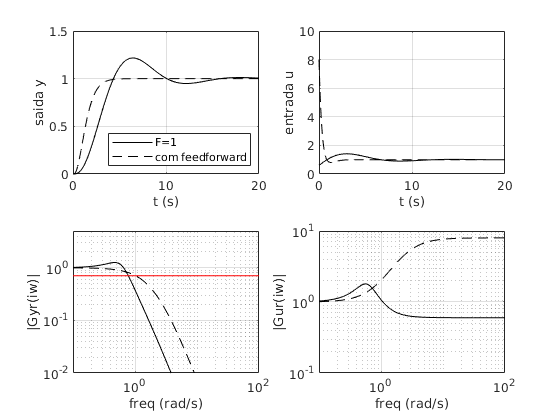

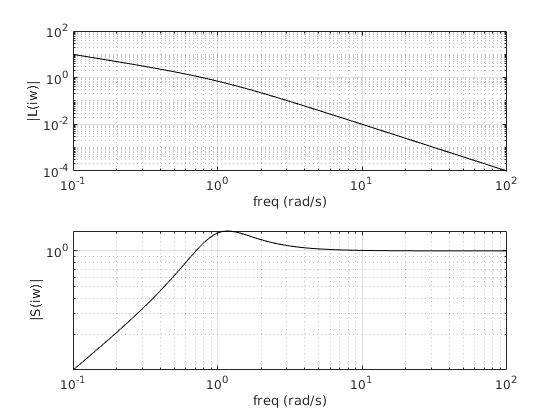

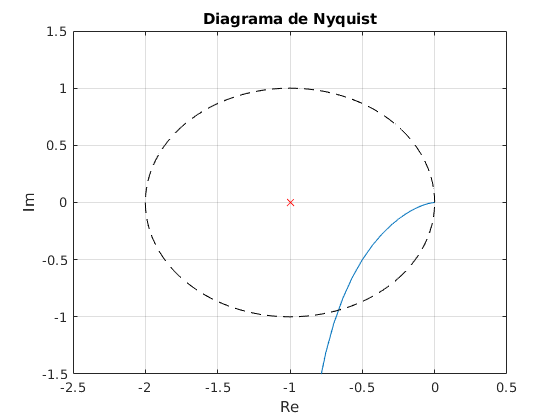

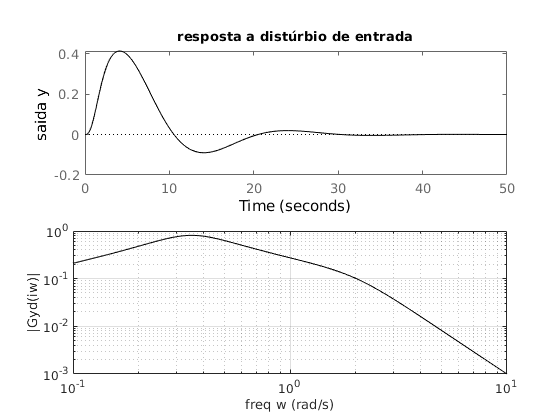

ans = struct with fields:
     GainMargin: [0 Inf]
    GMFrequency: [0 Inf]
    PhaseMargin: 52.5040
    PMFrequency: 48.3795
    DelayMargin: 0.0189
    DMFrequency: 48.3795
         Stable: 1


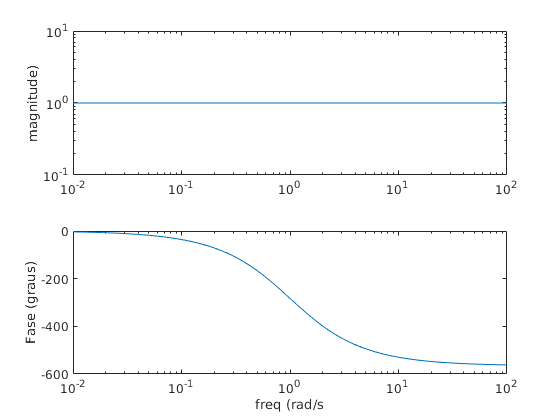

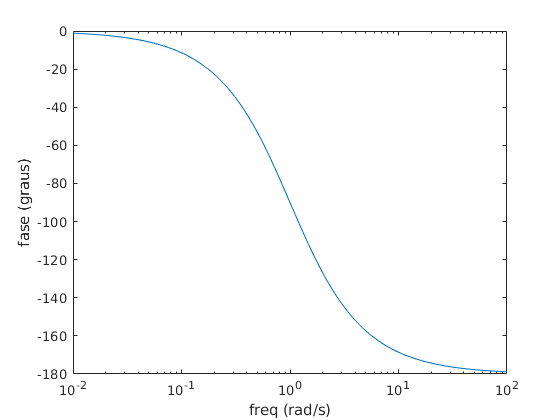

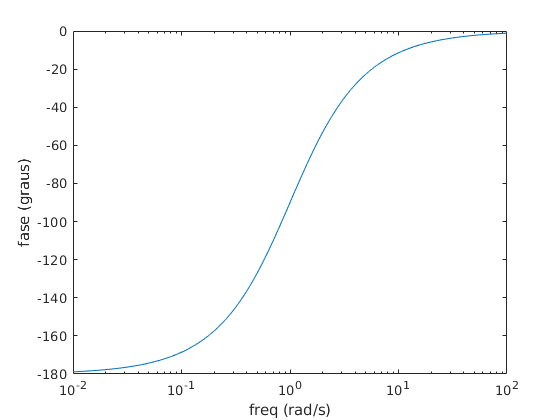

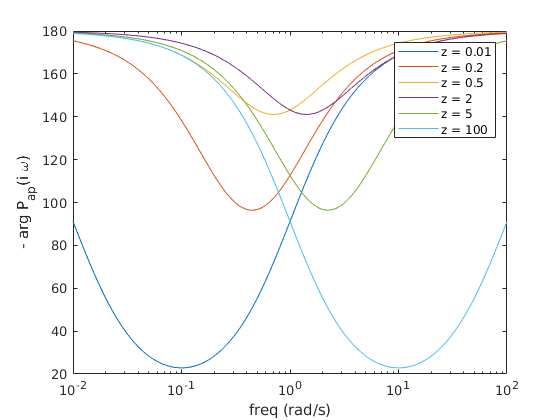

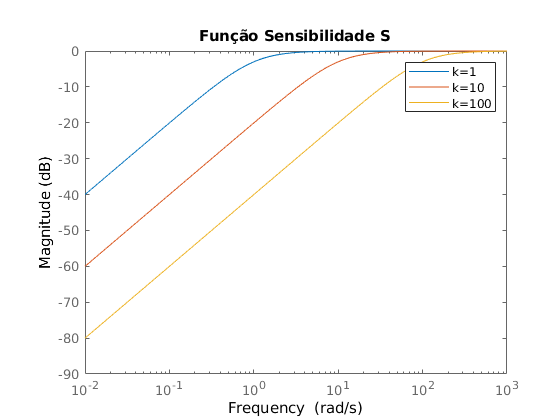

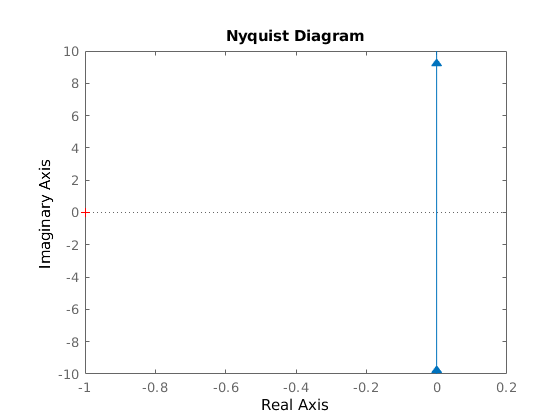

 place  Closed-loop pole assignment using state feedback.
 
    K = place(A,B,P) computes a state-feedback matrix K such that
    the eigenvalues of A-B*K are those specified in the vector P.
    No eigenvalue should have a multiplicity greater than the 
    number of inputs.
 
    [K,PREC] = place(A,B,P) returns PREC, an estimate of how
    closely the eigenvalues of A-B*K match the specified locations P
    (PREC measures the number of accurate decimal digits in the actual
    closed-loop poles).  A warning is issued if some nonzero closed-loop 
    pole is more than 10% off from the desired location. 
 
    See also acker.

    Documentation for place



ans =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i


 are  Algebraic Riccati Equation solution.
 
     X = are(A, B, C) returns the stablizing solution (if it
     exists) to the continuous-time Riccati equation:
 
            A'*X + X*A - X*B*X + C = 0
 
     assuming B is symmetric and nonnegative definite and C is
     symmetric.
 
     See also  ric, care, dare.



 lqr  Linear-quadratic regulator design for state-space systems.
 
    lqr computes the state-feedback control u = -K*x that minimizes
    the cost function
 
       J = Integral {x'Qx + u'Ru + 2*x'Nu} dt     (continuous time)
 
       J = Sum {x'Qx + u'Ru + 2*x'Nu}             (discrete time)
 
    for the state dynamics dx/dt = Ax+Bu or x[n+1] = Ax[n]+Bu[n].
 
    [K,S,CLP] = lqr(SYS,Q,R,N) calculates the optimal gain matrix K for the
    continuous or discrete state-space model SYS. lqr also returns the
    solution S of the associated algebraic Riccati equation and the 
    closed-loop poles CLP = EIG(A-B*K). The matrix N is set to zero when 
    omitted.
 
    [K,S,CLP] = lqr(A,B,Q,R,N) is an equivalent syntax for continuous-time
    models with dynamics dx/dt = Ax+Bu.
 
    Note: 
      * (A,B) must be stabilizable and [Q N;N' R] must be nonnegative
        definite.
      * The optimal cost is J

K =     0.4142    1.3522


ans =   -0.2500 + 0.9682i
  -0.2500 - 0.9682i


ans =    -2.0000
   -3.0000


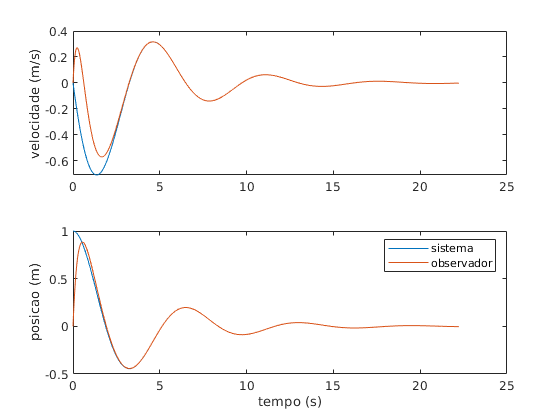

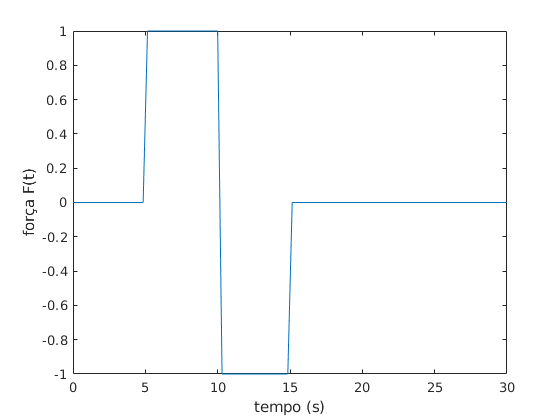

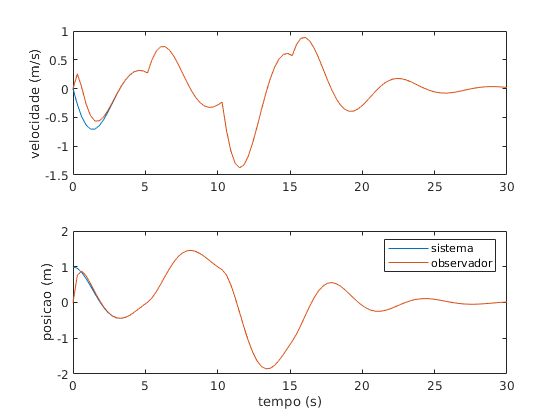

figure(); bode(L)

figure(); margin(L)
allmargin(L)